## SIOC 221A HW 5

## Kevin Okun

I certify that this represents my own work and that I have not worked with classmates or other individuals to complete this assignment.

Kevin M. Okun    10/28/2022

### Problem 1

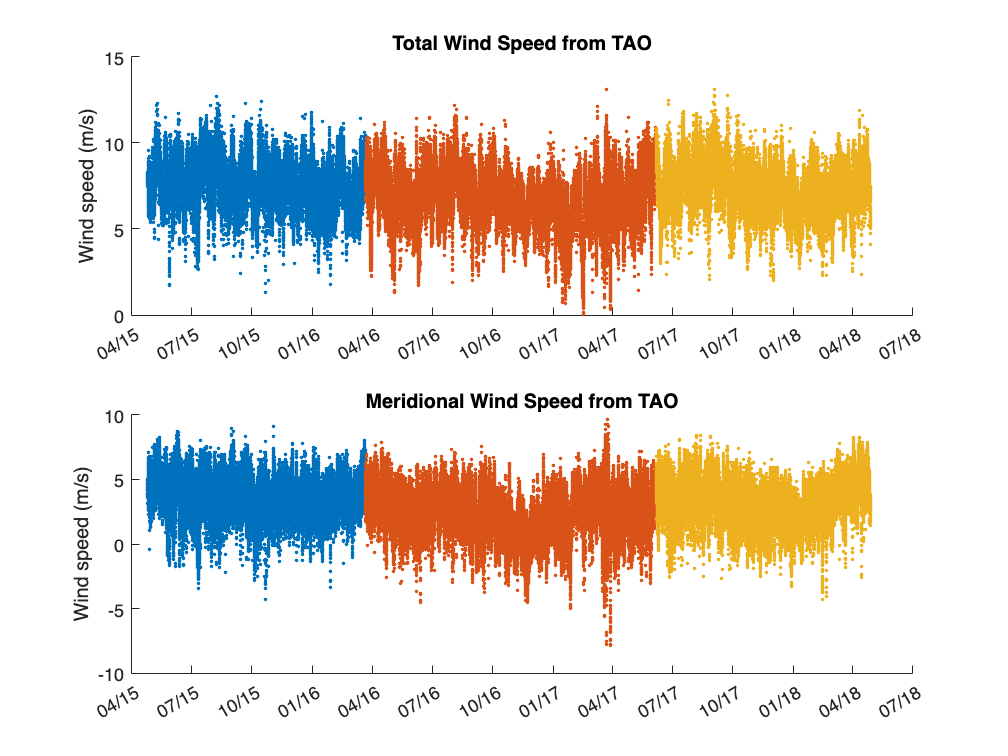

% Load data from Github
% Default is on KO's machine, so specify path below if needed
direc_str = '/Users/kevinokun/Documents/GitHub/SIO221a_Github_code/HW5_data';
cd(direc_str);
file_struct_names = ["year_2015", "year_2016", "year_2017"];

files = dir('*.nc');

% Create reference data to create time datestring
reference_date = datenum(1950,01,01);

for idx=1:length(files)
    data.(file_struct_names(idx)).time = ncread(files(idx).name,'TIME');
    data.(file_struct_names(idx)).time = data.(file_struct_names(idx)).time+reference_date;
    data.(file_struct_names(idx)).time_string = datetime(data.(file_struct_names(idx)).time,'ConvertFrom','datenum');
    data.(file_struct_names(idx)).start_time = ncreadatt(files(idx).name,'/','time_coverage_start');
    data.(file_struct_names(idx)).end_time = ncreadatt(files(idx).name,'/','time_coverage_end');
    data.(file_struct_names(idx)).wind_speed_tot = ncread(files(idx).name,'WSPD')';
    data.(file_struct_names(idx)).wind_speed_v = ncread(files(idx).name,'VWND')';
    data.(file_struct_names(idx)).wind_speed_u = ncread(files(idx).name,'UWND')';
    data.(file_struct_names(idx)).file_name = files(idx);
    
end

clearvars direc_str files idx reference_date

figure(201); clf

% Plot time series for total and meridional wind speeds
for idx = 1:length(file_struct_names)
    subplot 211
    hold on
    plot(data.(file_struct_names(idx)).time,data.(file_struct_names(idx)).wind_speed_tot,'.')
    subplot 212
    hold on
    plot(data.(file_struct_names(idx)).time,data.(file_struct_names(idx)).wind_speed_v,'.')
end

title('Meridional Wind Speed from TAO')
ylabel('Wind speed (m/s)')
datetick('x','mm/yy')
subplot 211
title('Total Wind Speed from TAO')
ylabel('Wind speed (m/s)')
datetick('x','mm/yy')


% List spacing between data points and time series
for idx = 1:length(file_struct_names)
    data.(file_struct_names(idx)).time_string(2)-data.(file_struct_names(idx)).time_string(1)
end

ans = duration
   00:10:00


ans = duration
   00:10:00


ans = duration
   00:10:00



for idx = 1:(length(file_struct_names)-1)
    data.(file_struct_names(idx+1)).time_string(1)-data.(file_struct_names(idx)).time_string(end)
end

ans = duration
   09:30:00


ans = duration
   22:10:00


The spacing between each point of all three series is 10 minutes, with some gaps. From the 2015 to 2016 series, there is a gap of 9 hours and 30 minutes, and there is a 22 hour and 10 minute gap between the 2016 and 2017 series. Missing data are represented by NaN values.

% Fill missing values with a linear interpolation and detrend
for idx = 1:length(file_struct_names)
    data.(file_struct_names(idx)).wind_speed_tot_interp = fillmissing(data.(file_struct_names(idx)).wind_speed_tot,'linear');
    data.(file_struct_names(idx)).wind_speed_v_interp = fillmissing(data.(file_struct_names(idx)).wind_speed_v,'linear');
    data.(file_struct_names(idx)).wind_speed_tot_detrend = detrend(data.(file_struct_names(idx)).wind_speed_tot_interp);
    data.(file_struct_names(idx)).wind_speed_v_detrend = detrend(data.(file_struct_names(idx)).wind_speed_v_interp);
end

#### Problem 2

% Segment data into overlapping windows
days_per_segment = 60;
points_per_segment = days_per_segment*26*6;
hann_window = 8/3*hann(points_per_segment);

for idx = 1:length(file_struct_names)
    num_segments(idx) = floor(length(data.(file_struct_names(idx)).wind_speed_tot_interp)/(points_per_segment/2));
    for idx2 = 1:(num_segments(idx)-1)
        data.(file_struct_names(idx)).wind_speed_tot_segmented(1:points_per_segment,idx2)...
            = data.(file_struct_names(idx)).wind_speed_tot_interp((1+(idx2-1)*points_per_segment/2):(points_per_segment+(idx2-1)*points_per_segment/2))';
        data.(file_struct_names(idx)).wind_speed_v_segmented(1:points_per_segment,idx2)...
            = data.(file_struct_names(idx)).wind_speed_v_interp((1+(idx2-1)*points_per_segment/2):(points_per_segment+(idx2-1)*points_per_segment/2))';
        % Detrend each segment and apply hanning window
        data.(file_struct_names(idx)).wind_speed_tot_segmented_detrend(:,idx2) = detrend(data.(file_struct_names(idx)).wind_speed_tot_segmented(:,idx2));
        data.(file_struct_names(idx)).wind_speed_v_segmented_detrend(:,idx2) = detrend(data.(file_struct_names(idx)).wind_speed_v_segmented(:,idx2));
        data.(file_struct_names(idx)).wind_speed_tot_hanning(:,idx2) = data.(file_struct_names(idx)).wind_speed_tot_segmented_detrend(:,idx2).*hann_window;
        data.(file_struct_names(idx)).wind_speed_v_hanning(:,idx2) = data.(file_struct_names(idx)).wind_speed_v_segmented_detrend(:,idx2).*hann_window;
    end
   
    % Average the data to make one time series
    data.(file_struct_names(idx)).wind_speed_tot_60d_averaged = mean(data.(file_struct_names(idx)).wind_speed_tot_hanning,2);
    data.(file_struct_names(idx)).wind_speed_v_60d_averaged = mean(data.(file_struct_names(idx)).wind_speed_v_hanning,2);
end

For years 2015, 2016, and 2017, there are 10, 13, and 9 overlapping segments, respectively. Each segment contains 9360 data points, taken at 10 minute intervals. The frequencies resolvable are from 0 to the Nyquist freq, which is 1/(2*10min), which is:

(1/2)*(1/10)*(60)*(24)

ans = 72

a total of 72 cycles per day. The frequency resolution for the windowed data will be smaller than for the entire time series, as we will see later.

#### Problem 3

% Spectra from 2015 using interpolated, detrended, and windowed data

idx = 1;

% fft of each
data.(file_struct_names(idx)).fft.wind_speed_tot_raw = fft(data.(file_struct_names(idx)).wind_speed_tot_interp);
data.(file_struct_names(idx)).fft.wind_speed_tot_detrend = fft(data.(file_struct_names(idx)).wind_speed_tot_detrend);
data.(file_struct_names(idx)).fft.wind_speed_tot_window = fft(data.(file_struct_names(idx)).wind_speed_tot_hanning);

data.(file_struct_names(idx)).fft.wind_speed_v_raw = fft(data.(file_struct_names(idx)).wind_speed_v_interp);
data.(file_struct_names(idx)).fft.wind_speed_v_detrend = fft(data.(file_struct_names(idx)).wind_speed_v_detrend);
data.(file_struct_names(idx)).fft.wind_speed_v_window = fft(data.(file_struct_names(idx)).wind_speed_v_hanning);

% Compute amp^2
data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_tot_raw(1:length(data.(file_struct_names(idx)).time)/2+1)).^2;

data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_tot_detrend(1:length(data.(file_struct_names(idx)).time)/2+1)).^2;


data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_v_raw(1:length(data.(file_struct_names(idx)).time)/2+1)).^2;

data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_v_detrend(1:length(data.(file_struct_names(idx)).time)/2+1)).^2;

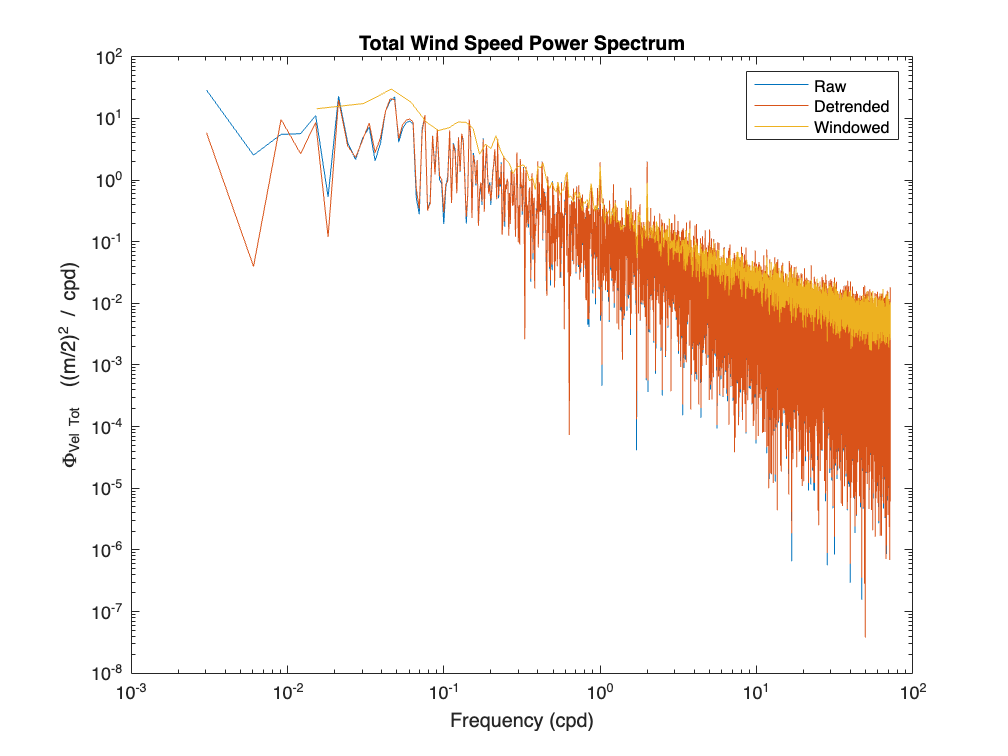


for idx2 = 1:(num_segments(idx)-1)
    data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp(:,idx2)=abs(data.(file_struct_names(idx)).fft.wind_speed_tot_window(1:points_per_segment/2+1,idx2)).^2;
    data.(file_struct_names(idx)).fft.wind_speed_v_window_amp(:,idx2)=abs(data.(file_struct_names(idx)).fft.wind_speed_v_window(1:points_per_segment/2+1,idx2)).^2;
end

% Average windowed data
data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = mean(data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp,2);
data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = mean(data.(file_struct_names(idx)).fft.wind_speed_v_window_amp,2);

% Setup frequency vector
dt=mean(diff(data.(file_struct_names(idx)).time),'omitnan');

% For full series
time_span=dt*length(data.(file_struct_names(idx)).time); % Find time span in series
df=1/time_span; % Frequency resolution
fn=1/2/dt;
frequency_vector=(0:df:fn)'; %frequency vector, cpd, goes from 0 to Nyquist

% For window
time_span_window=dt*points_per_segment; % Find time span in series
df_window=1/time_span_window; % Frequency resolution
frequency_vector_window=(0:df_window:fn)'; %frequency vector, cpd, goes from 0 to Nyquist


% Correct for MATLAB normalization
data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp / length(data.(file_struct_names(idx)).time).^2;
data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp / length(data.(file_struct_names(idx)).time).^2;
data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp / points_per_segment.^2;
data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp / length(data.(file_struct_names(idx)).time).^2;
data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp / length(data.(file_struct_names(idx)).time).^2;
data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp / points_per_segment.^2;

% Correct for lost variance from half spectrum
data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp.*2;
data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp.*2;
data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp.*2;
data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp.*2;
data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp.*2;
data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp.*2;

% Convert to correct units
data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp/df;
data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp/df;
data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp/df_window;
data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp = data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp/df;
data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp/df;
data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp/df_window;

% Plot spectra

figure(202); clf
loglog(frequency_vector,data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp)
hold on
loglog(frequency_vector,data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp)
loglog(frequency_vector_window,data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp)
title('Total Wind Speed Power Spectrum')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel Tot}  ((m/2)^2 / cpd)')
legend('Raw','Detrended','Windowed')

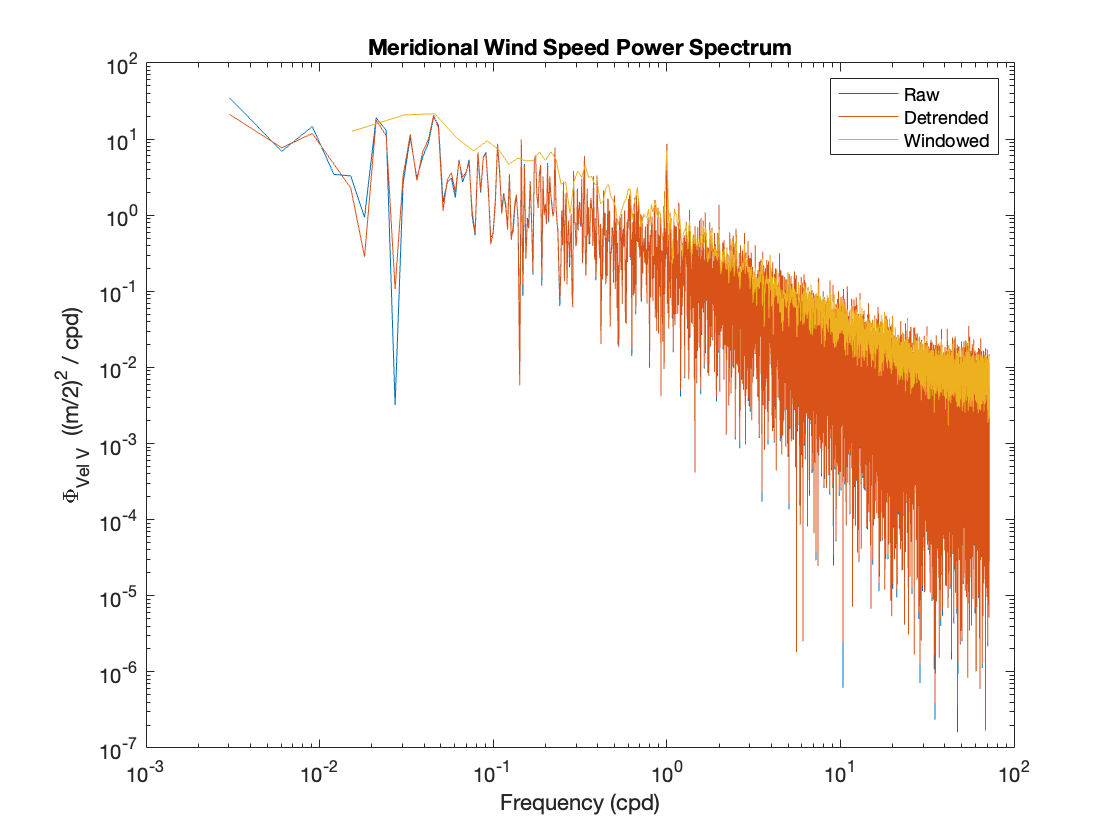


figure(203); clf
loglog(frequency_vector,data.(file_struct_names(idx)).fft.wind_speed_v_raw_amp)
hold on
loglog(frequency_vector,data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp)
loglog(frequency_vector_window,data.(file_struct_names(idx)).fft.wind_speed_v_window_amp)
title('Meridional Wind Speed Power Spectrum')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel V}  ((m/2)^2 / cpd)')
legend('Raw','Detrended','Windowed')

Detrending the data decreases the lowest frequency peak, which in this case is the fundamental frequency above the mean. The windowed data has a smaller frequency resolution due to the shortened time series length, so it has fewer points at the low frequency range, but lower noise. By eye, the diurnal peak is more noticeable in the windowed spectrum vs the others.

#### Problem 4

% Finding error bars using nu = 2*num_samples
nu = 2;
err_low_raw = nu/chi2inv(1-.05/2,nu)

err_low_raw = 0.2711

err_high_raw = nu/chi2inv(.05/2,nu)

err_high_raw = 39.4979


nu_window = 2*floor(length(data.(file_struct_names(idx)).fft.wind_speed_tot_raw_amp)/points_per_segment);
err_low_window = nu_window/chi2inv(1-.05/2,nu_window)

err_low_window = 0.3590

err_high_window = nu_window/chi2inv(.05/2,nu_window)

err_high_window = 8.2573

The uncertainties for the raw and the detrended data should be the same, since the length of the time series and number of averages is the same. The error for the windowed segment is lower, as expected, since it is averaged more.

#### Problem 5

% Average ffts together for detrended and windowed data
for idx = 1:3
    data.(file_struct_names(idx)).fft.wind_speed_tot_detrend = fft(data.(file_struct_names(idx)).wind_speed_tot_detrend(1:46782));
    data.(file_struct_names(idx)).fft.wind_speed_tot_window = fft(data.(file_struct_names(idx)).wind_speed_tot_hanning);

    data.(file_struct_names(idx)).fft.wind_speed_v_detrend = fft(data.(file_struct_names(idx)).wind_speed_v_detrend(1:46782));
    data.(file_struct_names(idx)).fft.wind_speed_v_window = fft(data.(file_struct_names(idx)).wind_speed_v_hanning);

    data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_tot_detrend(1:length(data.(file_struct_names(3)).time)/2+1)).^2;
    data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = abs(data.(file_struct_names(idx)).fft.wind_speed_v_detrend(1:length(data.(file_struct_names(3)).time)/2+1)).^2;

    for idx2 = 1:(num_segments(idx)-1)
        data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp(:,idx2)=abs(data.(file_struct_names(idx)).fft.wind_speed_tot_window(1:points_per_segment/2+1,idx2)).^2;
        data.(file_struct_names(idx)).fft.wind_speed_v_window_amp(:,idx2)=abs(data.(file_struct_names(idx)).fft.wind_speed_v_window(1:points_per_segment/2+1,idx2)).^2;
    end

    % Correct for MATLAB normalization
    data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp / length(data.(file_struct_names(3)).time).^2;
    data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp / points_per_segment.^2;
    data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp / length(data.(file_struct_names(3)).time).^2;
    data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp / points_per_segment.^2;

    % Correct for lost variance from half spectrum
    data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp.*2;
    data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp.*2;
    data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp.*2;
    data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp.*2;

    % Convert to correct units
    data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_detrend_amp/df;
    data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp = data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp/df_window;
    data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp = data.(file_struct_names(idx)).fft.wind_speed_v_detrend_amp/df;
    data.(file_struct_names(idx)).fft.wind_speed_v_window_amp = data.(file_struct_names(idx)).fft.wind_speed_v_window_amp/df_window;

     % Average windowed data
    data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp_mean = mean(data.(file_struct_names(idx)).fft.wind_speed_tot_window_amp,2);
    data.(file_struct_names(idx)).fft.wind_speed_v_window_amp_mean = mean(data.(file_struct_names(idx)).fft.wind_speed_v_window_amp,2);
end

combined_tot_detrend = [data.year_2015.fft.wind_speed_tot_detrend_amp data.year_2016.fft.wind_speed_tot_detrend_amp data.year_2017.fft.wind_speed_tot_detrend_amp];
combined_v_detrend = [data.year_2015.fft.wind_speed_v_detrend_amp data.year_2016.fft.wind_speed_v_detrend_amp data.year_2017.fft.wind_speed_v_detrend_amp];
wind_speed_tot_average = mean(combined_tot_detrend,2);
wind_speed_v_average = mean(combined_v_detrend,2);

combined_tot_window = [data.year_2015.fft.wind_speed_tot_window_amp data.year_2016.fft.wind_speed_tot_window_amp data.year_2017.fft.wind_speed_tot_window_amp];
combined_v_window = [data.year_2015.fft.wind_speed_v_window_amp data.year_2016.fft.wind_speed_v_window_amp data.year_2017.fft.wind_speed_v_window_amp];
wind_speed_tot_average_window = mean(combined_tot_window,2);
wind_speed_v_average_window = mean(combined_v_window,2);

% Adjust frequency vector
time_span=dt*length(data.(file_struct_names(3)).time); % Find time span in series
df=1/time_span; % Frequency resolution
fn=1/2/dt;
frequency_vector=(0:df:fn)';

% Finding error bars using nu = 2*num_samples
nu = 6;
err_low_detrend = nu/chi2inv(1-.05/2,nu)

err_low_detrend = 0.4152

err_high_detrend = nu/chi2inv(.05/2,nu)

err_high_detrend = 4.8491


nu_window = 2*floor(3*length(data.(file_struct_names(3)).fft.wind_speed_tot_detrend_amp)/points_per_segment);
err_low_window = nu_window/chi2inv(1-.05/2,nu_window)

err_low_window = 0.5360

err_high_window = nu_window/chi2inv(.05/2,nu_window)

err_high_window = 2.4872

The new error estimates are smaller than before. Plotting the spectra together:

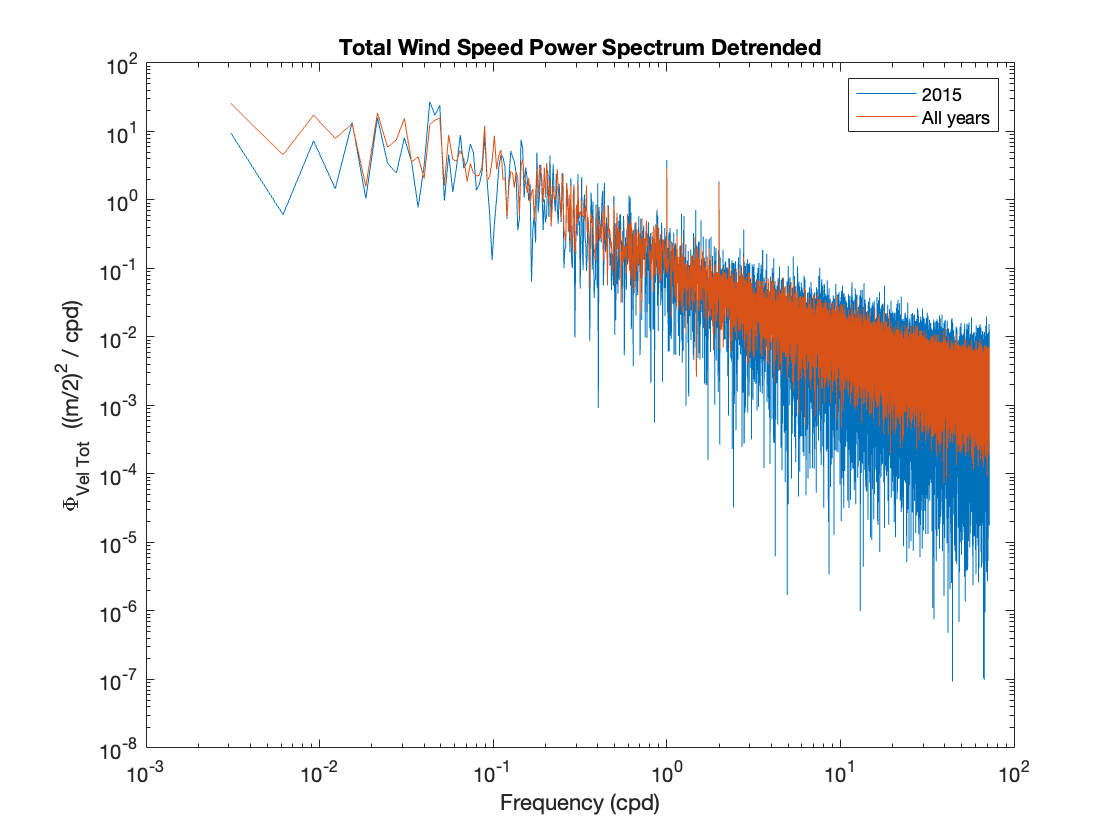

figure(204); clf
loglog(frequency_vector,data.(file_struct_names(1)).fft.wind_speed_tot_detrend_amp)
hold on
loglog(frequency_vector,wind_speed_tot_average)
title('Total Wind Speed Power Spectrum Detrended')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel Tot}  ((m/2)^2 / cpd)')
legend('2015','All years')

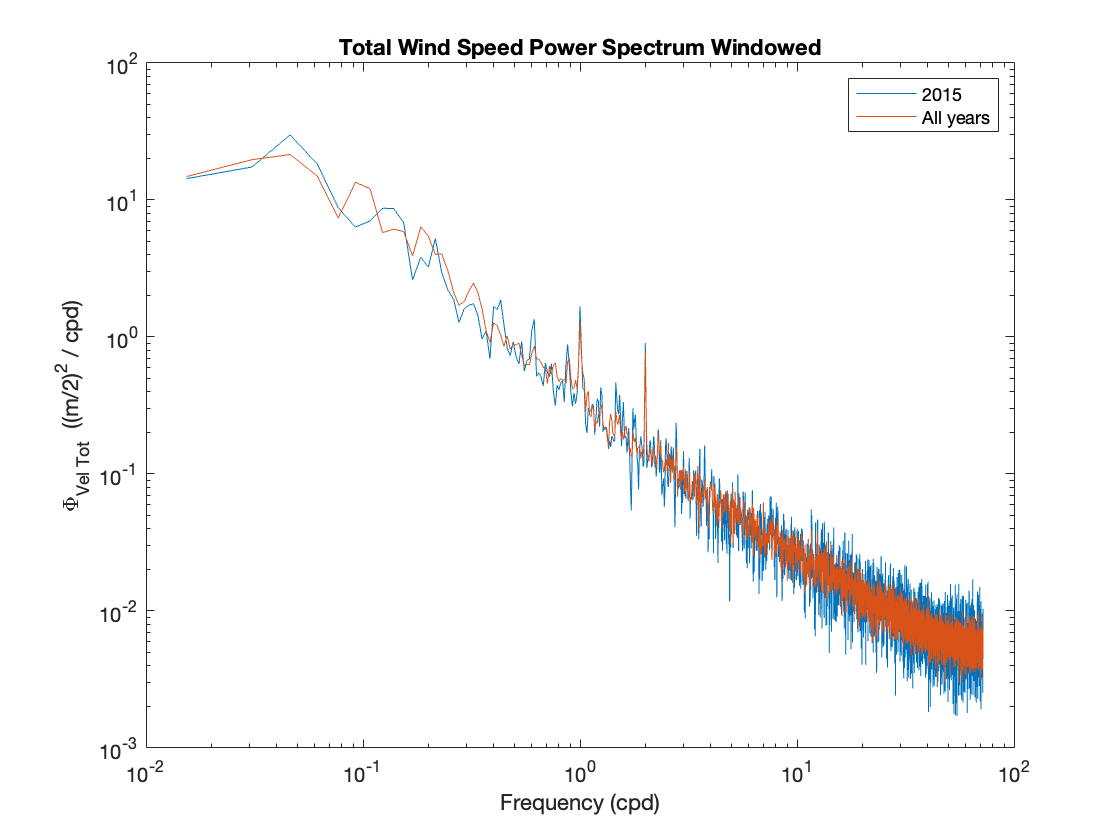


figure(205); clf
loglog(frequency_vector_window,data.(file_struct_names(1)).fft.wind_speed_tot_window_amp_mean)
hold on
loglog(frequency_vector_window,wind_speed_tot_average_window)
title('Total Wind Speed Power Spectrum Windowed')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel Tot}  ((m/2)^2 / cpd)')
legend('2015','All years')

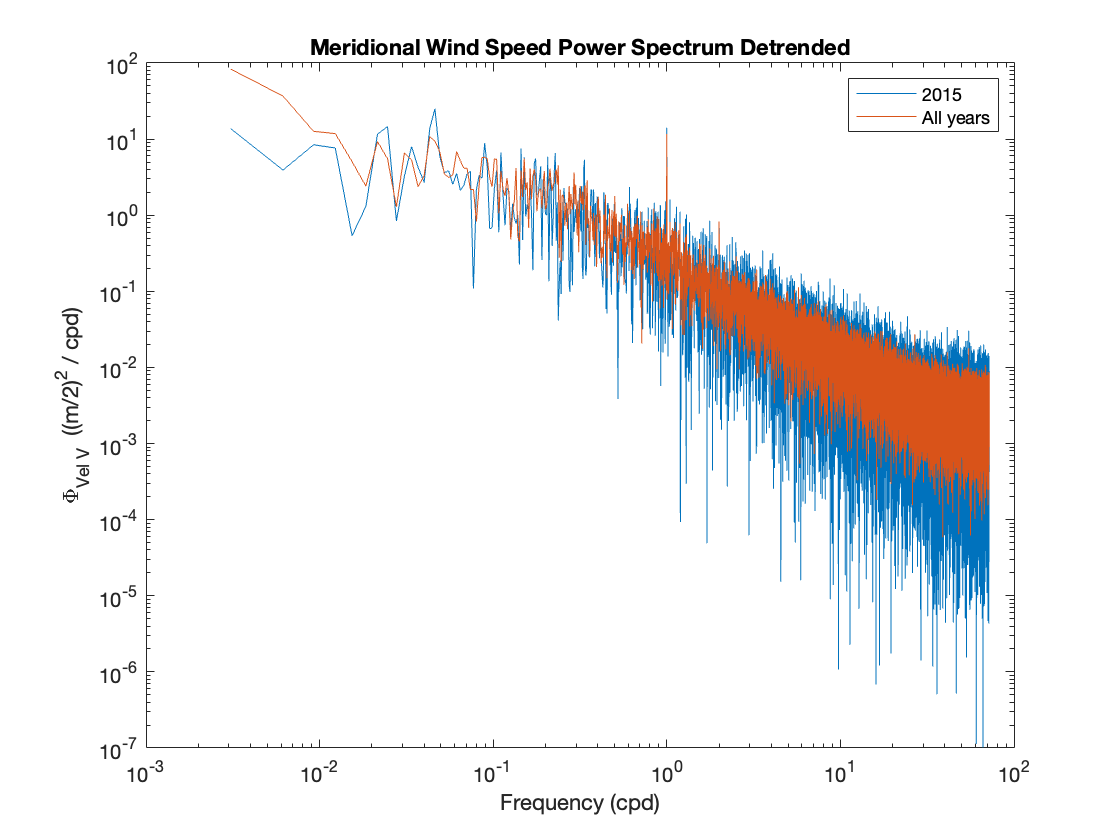


figure(206); clf
loglog(frequency_vector,data.(file_struct_names(1)).fft.wind_speed_v_detrend_amp)
hold on
loglog(frequency_vector,wind_speed_v_average)
title('Meridional Wind Speed Power Spectrum Detrended')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel V}  ((m/2)^2 / cpd)')
legend('2015','All years')

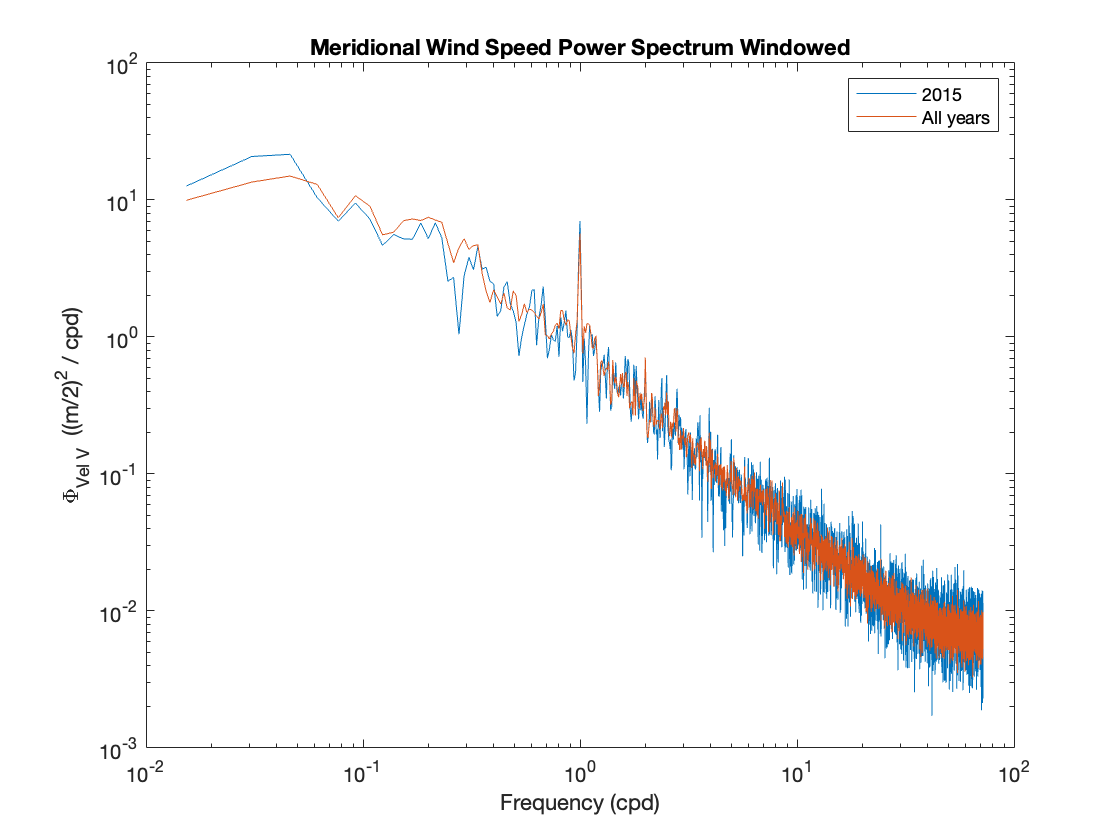


figure(207); clf
loglog(frequency_vector_window,data.(file_struct_names(1)).fft.wind_speed_v_window_amp_mean)
hold on
loglog(frequency_vector_window,wind_speed_v_average_window)
title('Meridional Wind Speed Power Spectrum Windowed')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel V}  ((m/2)^2 / cpd)')
legend('2015','All years')

The spectra that were averaged over multiple years have less noise because there are now three times as many samples per frequency vs the original. The uncertainty in the original spectrums for 2015 are high, and the averaged spectrum fall within its bounds, so the uncertainty can explain most of the variation.

#### Problem 6

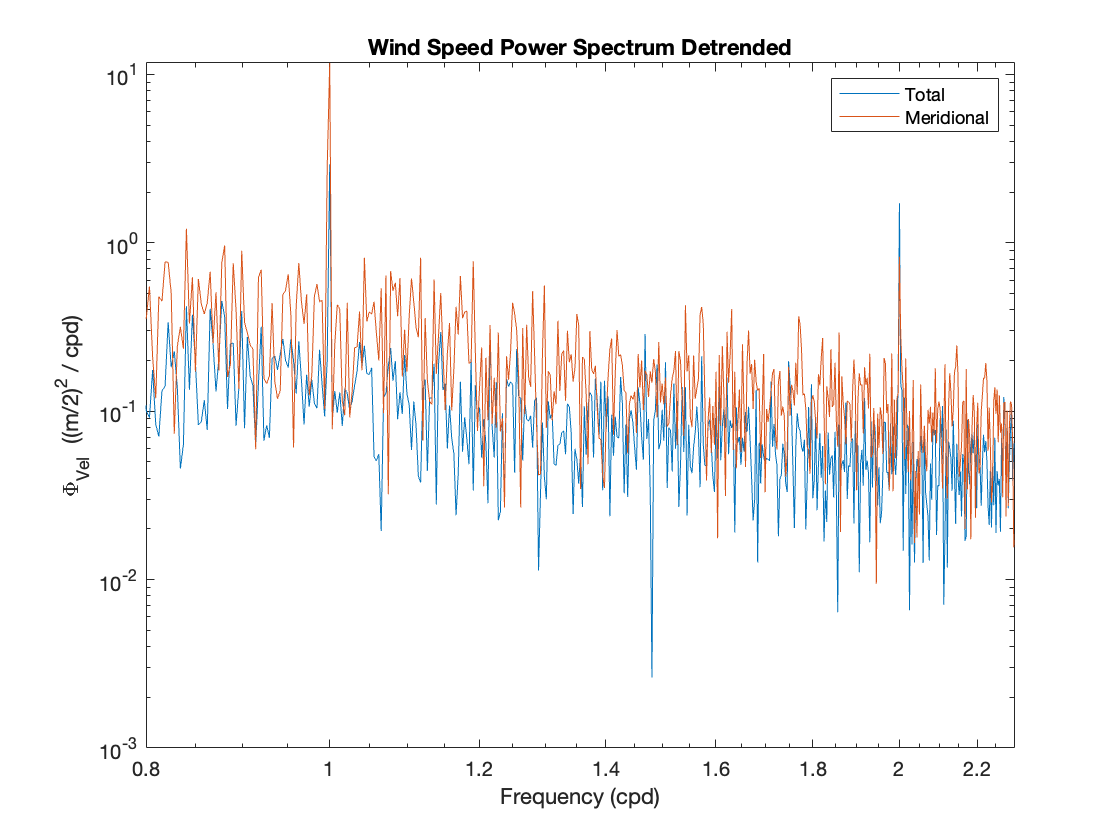

% Comparing meridional and total wind speeds
figure(208); clf
loglog(frequency_vector,wind_speed_tot_average)
hold on
loglog(frequency_vector,wind_speed_v_average)
title('Wind Speed Power Spectrum Detrended')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel}  ((m/2)^2 / cpd)')
legend('Total','Meridional')
xlim([0.8 2.3])

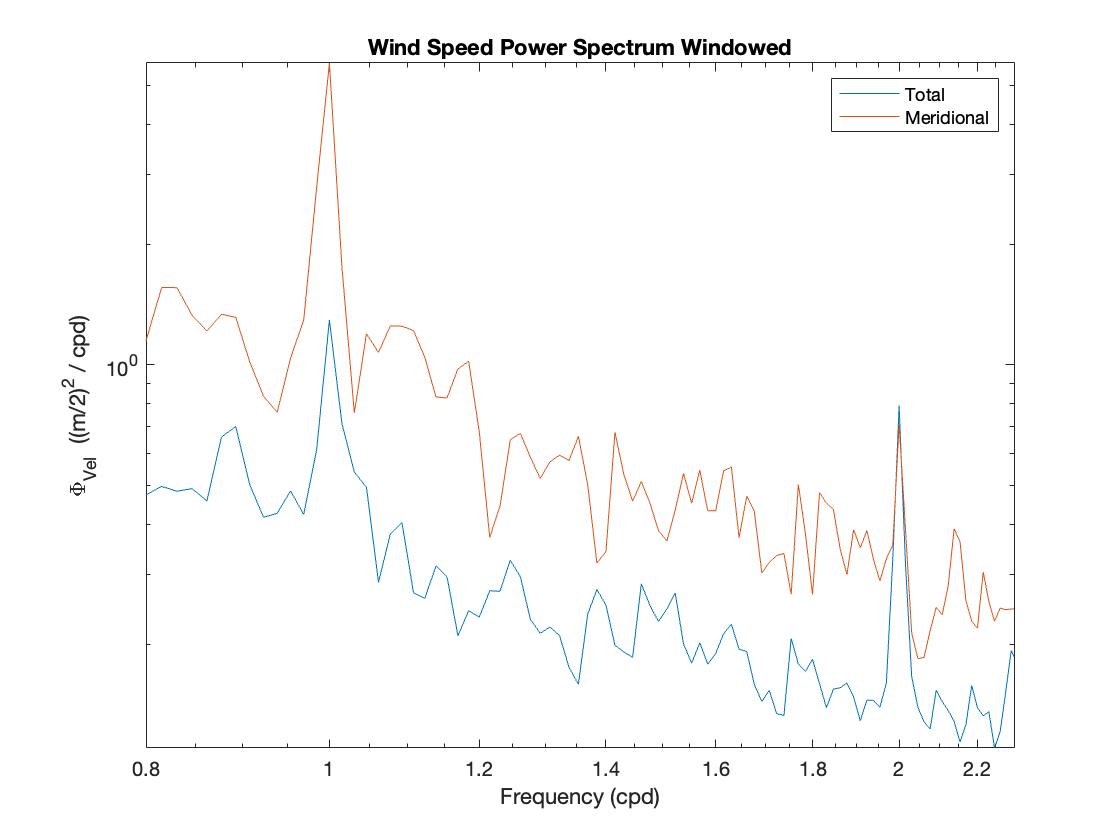


figure(209); clf
loglog(frequency_vector_window,wind_speed_tot_average_window)
hold on
loglog(frequency_vector_window,wind_speed_v_average_window)
title('Wind Speed Power Spectrum Windowed')
xlabel('Frequency (cpd)')
ylabel('\Phi_{Vel}  ((m/2)^2 / cpd)')
legend('Total','Meridional')
xlim([0.8 2.3])

In both the detrended and windowed data, and the correspionding 3-year averaged spectra, we see peaks at both the diurnal and semidiurnal frequencies. The peaks are above the error for the spectra in both cases, so they are significant. I think that since the daily cycles are so well defined, the peaks are narrow and don't contain a huge amount of energy compared to the rest of the bands in the spectrum, and the windowing emphasizes this since it looks at larger frequency bands per point.